# Compare full 3D camera motion with parallax estimate

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200;
numRays = 128;
filmResolution = 256;
pbrtLensFile = true; 
sceneChoice = "Cornell Box Reference";
% apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "Cornell Box Reference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.3.0mm.json');

Read 7 materials and 0 textures..



% add a skymap and a light
pbrtCPScene.thisR.set('skymap','room.exr','rotation val',[-90 180 0]);

lightName = 'from camera';
ourLight = piLightCreate(lightName,...
                        'type','distant',...
                        'cameracoordinate', true);

pbrtCPScene.thisR.set('light', ourLight,'add');

% for use later
baseR = pbrtCPScene.thisR;


## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorCreate('imx363'); 

ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

Elapsed time is 0.129182 seconds.
Started Docker (status 0): docker  --context remote-mux run -d -it  --gpus device=0  --name pbrt-gpu-Windows1015  -v /home/david/iset/iset3d-v4/local:/iset/iset3d-v4/local  digitalprodev/pbrt-v4-gpu-ampere-mux bash
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.85 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Rendered remotely in: 35.91 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d/local/cornell_box/renderings ...
done (  0.95 sec)

Output file:  renderings/cornell_box.exr
*** Rendering time (cornell_box) was 41.2 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compre

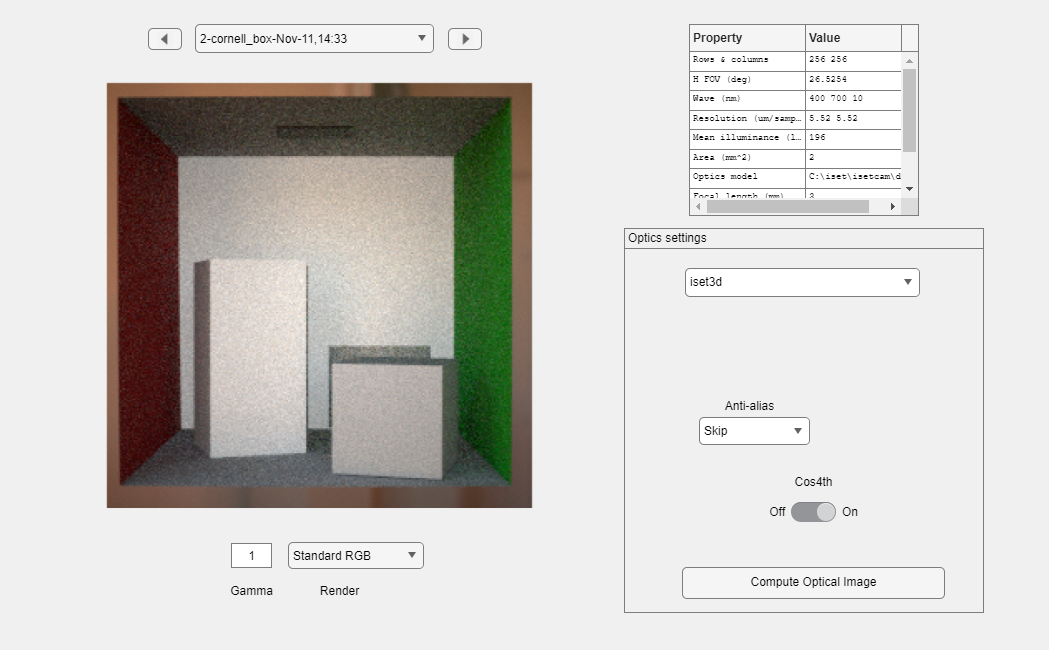

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

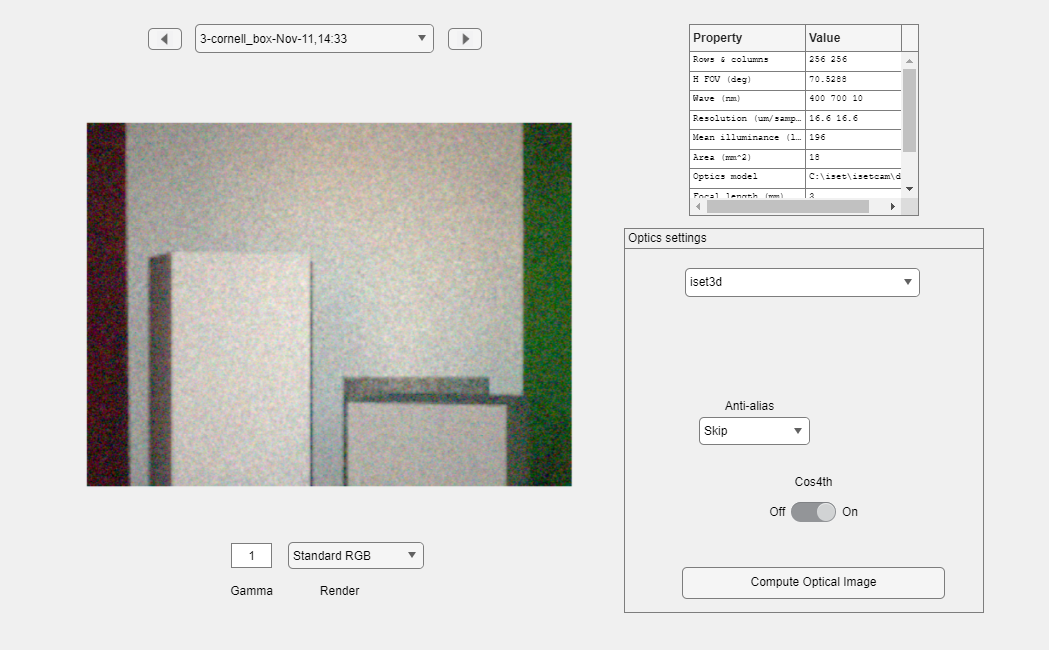

Elapsed time is 0.084450 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.85 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Rendered remotely in: 7.29 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d/local/cornell_box/renderings ...
done (  1.07 sec)

Output file:  renderings/cornell_box.exr
*** Rendering time (cornell_box) was 10.1 sec ***



Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.85 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Rendered remotely in: 3.75 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d/local/cornell_box/renderings ...
done (  1.30 sec)

Output file:  renderings/cornell_box.exr
*** Rendering time (cornell_box) was 6.9 sec ***

Elapsed time is 0.074379 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.86 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd

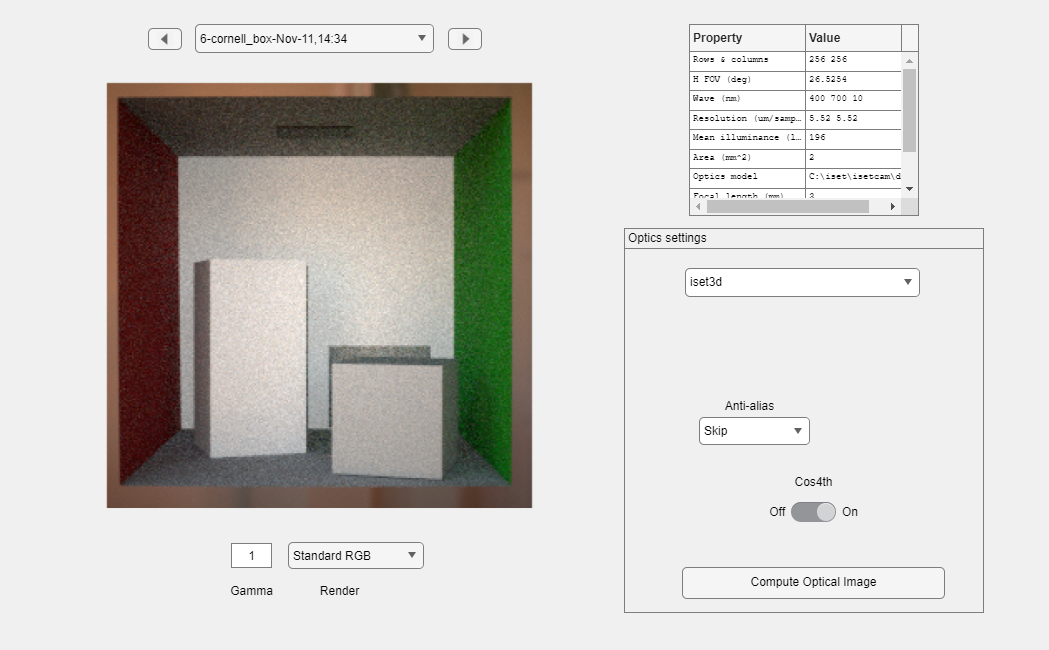

imshow(autoImage);

% hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
%    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
%    'insensorIP', true);

% our burst camera doesn't get the whole scene by default
% try using the FOV from the Auto camera
%hFOV = oiGet(oi,'hfov');
%sensor = sensorSetSizeToFOV(sensor,hFOV,oi);

tic
burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

disp('Full 3d render: ');

Full 3d render: 


toc

Elapsed time is 16.971550 seconds.


% cpCompareImages(hdrSensorImage, burstSensorImage, 'HDR vs Burst with no moion');


## Now we add a small amount of camera motion

Combining multiple frames into a single image can either be done at the sensor level, or a higher-level in the ISP. At the sensor level the default strategies implemented by ISETCam are to compute a normalized sum of the individual frames for Burst mode, and select the image with the most signal at each pixel for HDR. Once there is camera motion, though, those algorithms create errors in registration.

Elapsed time is 0.178798 seconds.
Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (1.07 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Rendered remotely in: 7.30 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d/local/cornell_box/renderings ...
done (  0.96 sec)

Output file:  renderings/cornell_box.exr
*** Rendering time (cornell_box) was 10.7 sec ***

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "c

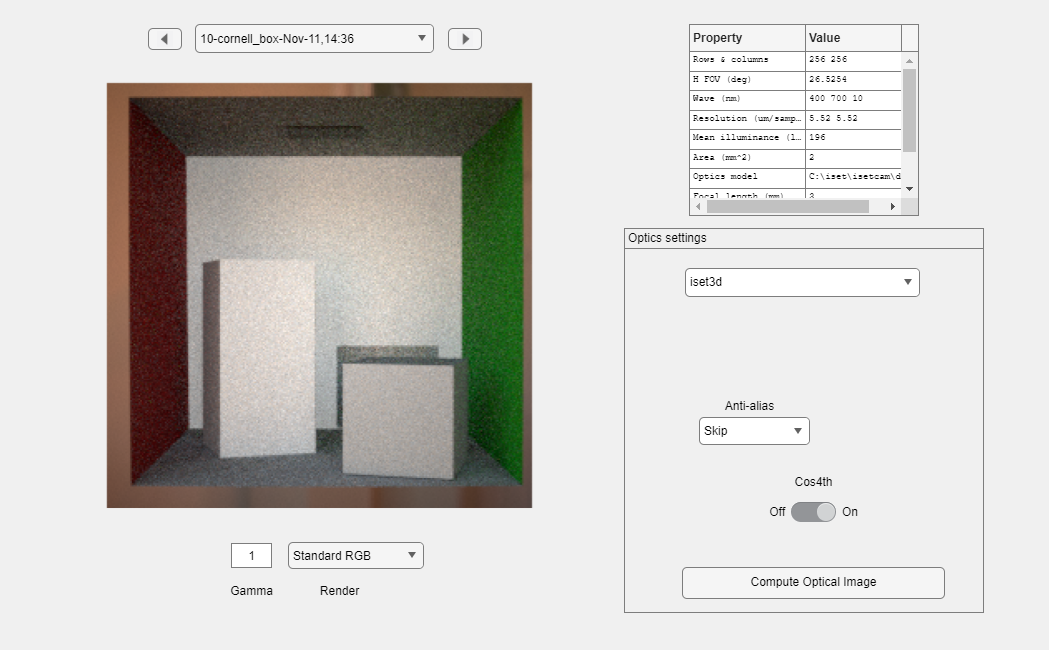

pbrtCPScene.cameraMotion = {{'unused', [.008, 0, 0], [0, 0, 0]}}; % first tuple is translation, second is rotation

tic
burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst with Motion',...
    'insensorIP',true);

disp('Full 3d motion render: ');

Full 3d motion render: 


toc

Elapsed time is 17.071766 seconds.


## Motion Simulation Using Parallax

Re-rendering the optical image for each frame in a scene that includes motion is computationally-expensive. So we have implemented an estimation using the depth map from our OI to create a shifted OI where the amount of the shift is based on the inverse of object depth.

% define our camera motion
motionAmounts = {[0 .01], [0 .02]}; % Assumes 3-frames 
% Create baseline OI
oi = piRender(baseR);

Put: wsl rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /mnt/c/iset/iset3d/local/cornell_box/ david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/ ...
Done (0.84 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows1015 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Rendered remotely in: 6.97 sec
Pull: wsl rsync -r  david@171.64.204.112:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d/local/cornell_box/renderings ...
done (  1.18 sec)

Output file:  renderings/cornell_box.exr
*** Rendering time (cornell_box) was 10.0 sec ***



% compute exposure from first OI
aeMethod = 'specular';
aeLevels = .8;
aeTime = autoExposure(oi,sensor, aeLevels, aeMethod);

tic
oiBurst = oiCameraMotion(oi,'amount',motionAmounts);
burstFrames = 3;
burstTimes = repelem(aeTime/burstFrames, burstFrames);

hFOV = oiGet(oi,'hfov');
sensor = sensorSetSizeToFOV(sensor,hFOV,oi);

sensor_burst = sensorSet(sensor,'exp time',burstTimes);
sensor_burst = sensorSet(sensor_burst, 'exposure method', 'burst');
sensor_burst = sensorCompute(sensor_burst,oiBurst);
disp('2.5d motion render: ');

2.5d motion render: 


toc

Elapsed time is 1.296296 seconds.


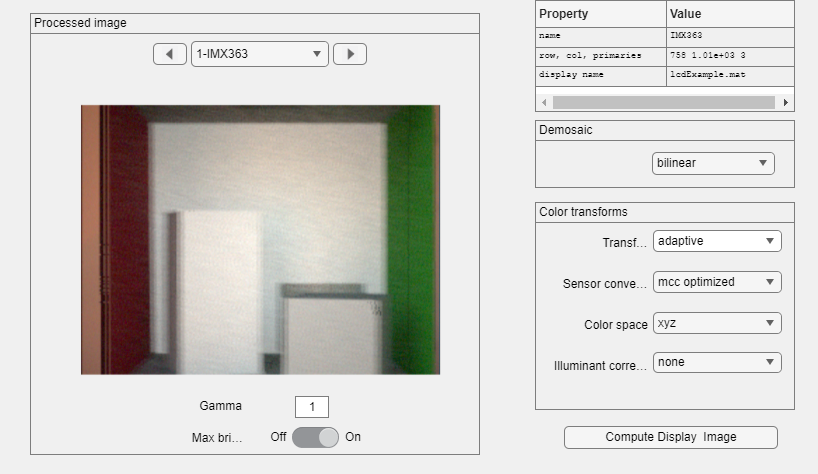


ip = ipCreate();
ip = ipCompute(ip,sensor_burst);
ipWindow(ip);

3D vs 2.5D

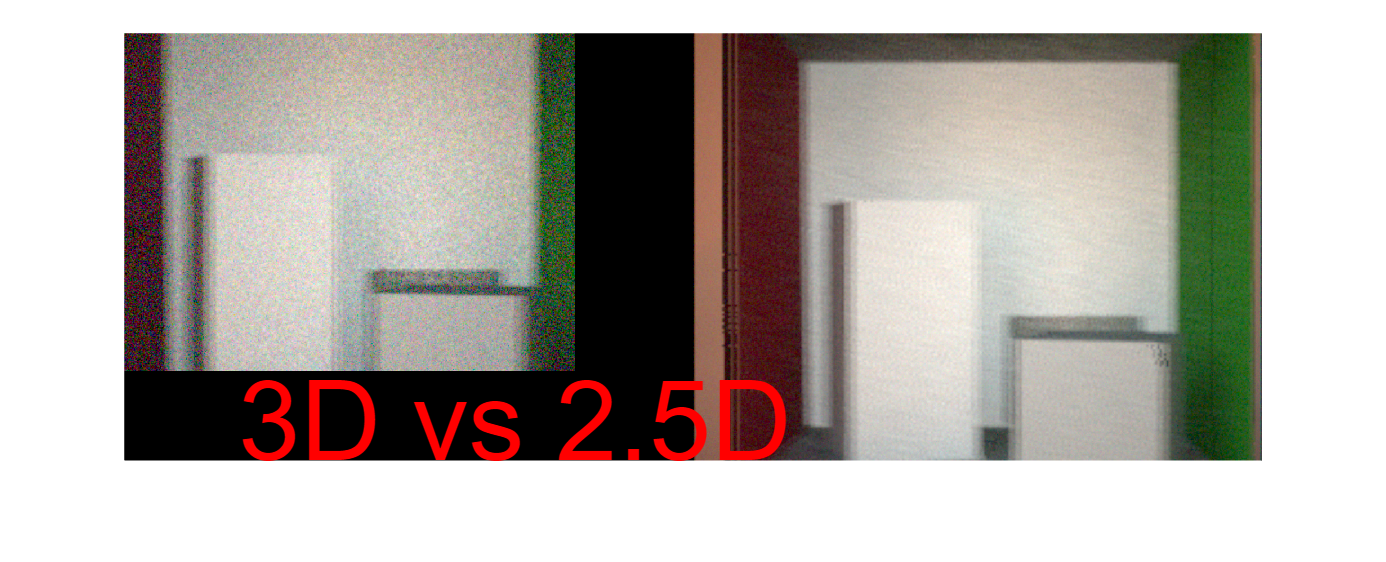


cpCompareImages(burstMotionImage, ip, "3D vs 2.5D");

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: Intel Intel(R) Iris(R) Xe Graphicswith driver version: 4.5.0 - Build 31.0.101.3790


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 70.1094 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 283.2814 total seconds.
